% by the Intelligent Unmanned Systems Laboratory, Westlake University, 2024
% 该框架只能用在书本的网格世界中。对于更一般形式的用树表示的拓扑关系不适用；尤其是该框架下状态转移是确定的。
clear 
close all

% Initialize environment parameters
agent_state = [1, 1];
final_state = [2, 2];
obstacle_state = [2, 1];
x_length = 2;
y_length = 2;
gamma = 0.9;
state_space = x_length * y_length;     % 状态个数
state=1:state_space;         % 纯为了在网格上标注名字
state_value=zeros(state_space,1);

reward_forbidden = -1;
reward_target = 1;
reward_step = 0;  % 注意根据仿射变化不改变最优策略，通常情况没有用处

% Define actions: up, right, down, left, stay
actions = {[0, -1], [1, 0], [0, 1], [-1, 0], [0, 0]};

% Initialize a cell array to store the action space for each state
action_space = cell(state_space, 1);

% Populate the action space
for i = 1:state_space       
    action_space{i} = actions;
end

number_of_action=5;

policy=zeros(state_space, number_of_action); % policy can be deterministic or stochastic, shown as follows:

% stochastic policy 

for i=1:state_space    %行和为1   即使行和不为1，也可能训练出结果。但是未必收敛 行和为1是确保了贝尔曼方程迭代的收敛性
    policy(i,:)=1/length(actions);         
end
% policy(3,2)=0; policy(3,4)=.4;
% policy(5,5)=0; policy(5,3)=.4;
policy(7,3)=0 ; policy(7,4)= 0; policy(7,2)= 0; policy(7,1)= 0; policy(7,5)= 1;  % 确定的策略
% policy(6,2)=0; policy(6,3) = 1; policy(6,4) = 0; policy(6,5) = 0; policy (6,1) = 0;

% Initialize the episode
episode_length = 1000;

state_history = zeros(episode_length, 2);   % 状态历史的坐标
reward_history = zeros(episode_length, 1);  

% Set the initial state
state_history(1, :) = agent_state;

% figure_plot(x_length, y_length, agent_state, final_state, obstacle_state, state_value, state, 1, state_history, policy, actions);


% for step = 1:episode_length
    for si = 1:length(state_space)
        siy = ceil(si/x_length);
        six = si-(siy-1)*x_length;
        for ai = 1:length(actions)
            q(ai)=q_pi([six,siy], action_space{si}{ai}, x_length, y_length, final_state, obstacle_state, reward_forbidden, reward_target, reward_step, gamma, state_value);
        end
        qrecord(si,:) = q;
    end
% end

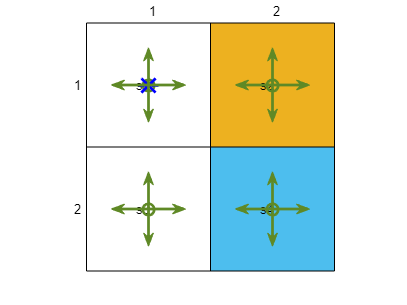


for step = 1:episode_length
    action = stochastic_policy(state_history(step, :), action_space, policy, x_length, y_length);   
    % Calculate the new state and reward
    [new_state, reward] = next_state_and_reward(state_history(step, :), action, x_length, y_length, final_state, obstacle_state, reward_forbidden, reward_target, reward_step);
    % Update state and reward history
    state_history(step+1, :) = new_state;
    reward_history(step) = reward;
end

figure_plot(x_length, y_length, agent_state, final_state, obstacle_state, state_value, state, episode_length, state_history, policy, actions);

function q=q_pi(state, action, x_length, y_length, target_state, obstacle_state, reward_forbidden, reward_target, reward_step, gamma, state_value)
        % 在state下执行action。检查是否到达target_state；是否到obstacle_state，如果是则扣分，并呆在该状态；检查是否撞墙，如果撞墙则弹回并扣分。
    new_x = state(1) + action(1);
    new_y = state(2) + action(2);
    new_state = [new_x, new_y];

    % Check if the new state is out of bounds
    if new_x < 1 || new_x > x_length || new_y < 1 || new_y > y_length
        new_state = state;
        reward = reward_forbidden;
    elseif ismember(new_state, obstacle_state, 'rows')
        % If the new state is an obstacle
        reward = reward_forbidden;
    elseif isequal(new_state, target_state)
        % If the new state is the target state
        reward = reward_target;
    else
         % If the new state is a normal cell
        reward = reward_step;
    end
    
    state_1d = x_length * (state(2)-1) + state(1);   % 转到s_i编号的状态
    Gt1 = gamma*state_value(state_1d);   % determinatstic 的转移

    q = reward + Gt1;
end